clc 
close all
x=input("enter your sequence")

x =      1     2     3     4


N=input("enter the no. of points of DFT")

N = 4

NO=input("Enter the time shift")

NO = 2

for k=0:N-1
    for n=0:N-1
        M(k+1,n+1)=exp((-1i*2*pi*k*n)/N)*exp((-1i*2*pi*NO*k)/N);
    end
end
L=length(x);
if(L<=N)
    xn=[x zeros(1,N-L)];
else xn=x(1,N)
end
Xk=M*xn.'

Xk =   10.0000 + 0.0000i
   2.0000 - 2.0000i
  -2.0000 - 0.0000i
   2.0000 + 2.0000i


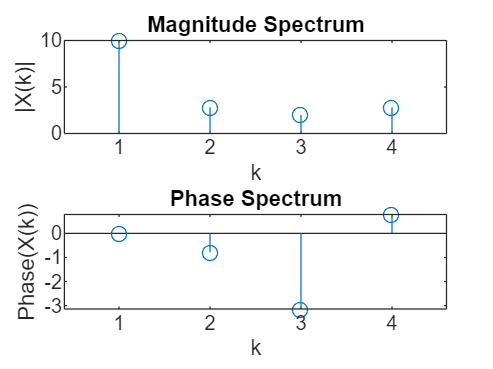

k=1:1:N;

subplot(2,1,1)
stem(k, abs(Xk))
title('Magnitude Spectrum')
xlabel('k')
ylabel('|X(k)|')
subplot(2,1,2)
stem(k, angle(Xk))
title('Phase Spectrum')
xlabel('k')
ylabel('Phase(X(k))')